# Figures of average acoustic features per bat

BaseDataDir = '/Volumes/server_home-1/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BoxPath = '/Users/elie/Box';
Path2Paper = fullfile(BoxPath, 'BatmanData', 'Deaf Paper');
% load data from all calls, obtained in Notebook
% DeafBats_Figure2_AveragePAF.mlx 
All = load(fullfile(LocalDataDir, "Data4_SupFigue2_AllCalls.mat"));
% load data from male acoustic group 4, obtained in Notebook
% DeafBats_Figure14_AveragePAFG4Males.mlx
Males = load(fullfile(LocalDataDir, "Data4_SupFigue2_PAF_MalesAcGroup4_Calls.mat"));
% load data from female acoustic group 1, obtained in Notebook
% DeafBats_Figure15_AveragePAFG1Females.mlx
Females = load(fullfile(LocalDataDir, "Data4_SupFigue2_PAF_FemalesAcGroup1_Calls.mat"));

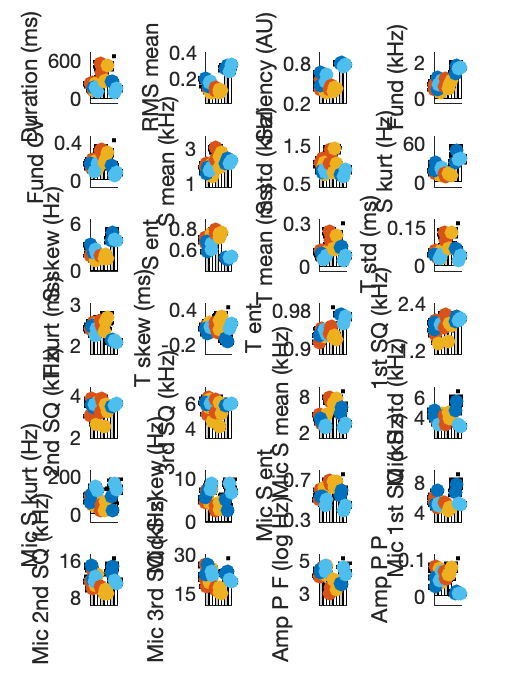

Fig1 = figure(1);
clf
T=tiledlayout(7,4,'TileSpacing','compact');
set(gcf,'Visible','on')

AcVarMean_HD = [All.AcVarMean_HD Females.AcVarMean_HD Males.AcVarMean_HD];
AcVarSE_HD = [All.AcVarSE_HD Females.AcVarSE_HD Males.AcVarSE_HD];
AcVar_mean_pBat = [All.AcVar_mean_pBat Females.AcVar_mean_pBat Males.AcVar_mean_pBat];
AcVar_se_pBat = [All.AcVar_se_pBat Females.AcVar_se_pBat Males.AcVar_se_pBat];

for vv=1:length(All.AcVars)
    N=nexttile(vv,[1,1]);
    
    Col_pBat = [All.Col_pBat{vv}; Females.Col_pBat{vv}; Males.Col_pBat{vv}];
    
    Rand = [(rand(1,length(All.BatSexDeaf)/2)+0.2).*0.75 (rand(1,length(All.BatSexDeaf)/2)*(-1)-0.2).*0.75];
    Rand = Rand(randperm(length(Rand)));
    XHorD = ones(size(All.BatSexDeaf)) + Rand;
    XHorD(contains(All.BatSexDeaf, 'Saline')) = XHorD(contains(All.BatSexDeaf, 'Saline'))+2;
    XHorD = [XHorD 5+([0.33 0.66 1.5 2.33 2.66 3.5])];
    XHorD = [XHorD 10+([0.5 1.5 2.5 3.5])];
    
    errorbar([1 3 6 8 11 13],AcVarMean_HD(vv,:), zeros(1,length(AcVarSE_HD(vv,:))), 2*AcVarSE_HD(vv,:), 'k.','LineWidth',2)
    hold on
    B=bar([1 3 6 8 11 13], AcVarMean_HD(vv,:));
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    B.CData(3,:) = 0.8*ones(1,3);
    B.CData(4,:) = ones(1,3);
    B.CData(5,:) = 0.8*ones(1,3);
    B.CData(6,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 2*AcVar_se_pBat(vv,:), 'k.','LineWidth',2)
    hold on
    scatter(XHorD,AcVar_mean_pBat(vv,:),50, Col_pBat, 'filled')
    ylabel(sprintf('%s', All.AcVars{vv}), 'FontSize',12)
    XLim = [0 14];
    set(gca, 'XLim', XLim);
    % YLim = get(gca, 'YLim');
    MinVal = min(AcVar_mean_pBat(vv,:)-2*AcVar_se_pBat(vv,:));
    MaxVal = max([AcVar_mean_pBat(vv,:)+2*AcVar_se_pBat(vv,:) AcVarMean_HD(vv,:) + 2*AcVarSE_HD(vv,:)]);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
    
    set(gca, 'YLim', YLim)
    set(gca, 'XTick', [])

    % if vv>24
    %     set(gca, 'XTick', [1 3],'XTickLabel', {'Deaf' 'Hearing'}, 'FontSize',12)
    % else
    %     set(gca, 'XTick', [1 3 6 8 11 13],'XTickLabel', {'' ''})
    % end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)], 'FontSize',10)
    hold off
    if All.Tbl_pvalues.LME(vv)<0.01
        hold on
        plot([1 3], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
    end
    if Females.Pvalue_matrix_LME(vv)<0.01
        hold on
        plot([6 8], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
    end
    if Males.Pvalue_matrix_LME(vv)<0.01
        hold on
        plot([11 13], (18/20*diff(YLim) + YLim(1)).*ones(1,2), '-','Color','k', 'LineWidth',2)
        hold on
    end
    N.Box = 0;
end

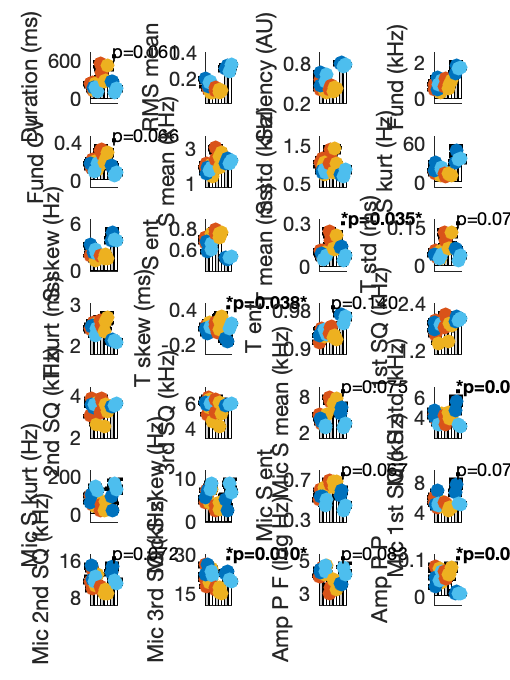

for vv=1:length(All.AcVars)
    YLabel = Fig1.Children.Children(vv).YLabel.String;
    IndAcVars = contains(Females.AcVars,YLabel);
    if All.Tbl_pvalues.LME(IndAcVars)<0.01
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        YLim = Fig1.Children.Children(vv).YLim;
        hold on
        if All.Tbl_pvalues.LME_FDR(IndAcVars)<0.05
            text(Fig1.Children.Children(vv),0,(diff(YLim) + YLim(1)), sprintf('*p=%.3f*', All.Tbl_pvalues.LME_FDR(IndAcVars)),'FontSize', 9, 'FontWeight','bold')
        else
            text(Fig1.Children.Children(vv),0,(diff(YLim) + YLim(1)), sprintf('p=%.3f', All.Tbl_pvalues.LME_FDR(IndAcVars)),'FontSize', 9)
        end
    end
    if Females.Pvalue_matrix_LME(IndAcVars)<0.01
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        YLim = Fig1.Children.Children(vv).YLim;
        hold on
        if Females.Pvalue_matrix_LME_FDR(IndAcVars)<0.05
            text(Fig1.Children.Children(vv),6,(diff(YLim) + YLim(1)), sprintf('*p=%.3f*', Females.Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9, 'FontWeight','bold')
        else
            text(Fig1.Children.Children(vv),6,(diff(YLim) + YLim(1)), sprintf('p=%.3f', Females.Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9)
        end
    end
    if Males.Pvalue_matrix_LME(IndAcVars)<0.01
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        YLim = Fig1.Children.Children(vv).YLim;
        hold on
        if Males.Pvalue_matrix_LME_FDR(IndAcVars)<0.05
            text(Fig1.Children.Children(vv),11,(diff(YLim) + YLim(1)), sprintf('*p=%.3f*', Males.Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9, 'FontWeight','bold')
        else
            text(Fig1.Children.Children(vv),11,(diff(YLim) + YLim(1)), sprintf('p=%.3f', Males.Pvalue_matrix_LME_FDR(IndAcVars)),'FontSize', 9)
        end
    end
end

Fig1.Units = 'centimeters';
Fig1.Position(3:4) = [9 12];
Fig1.PaperSize = [9 12];
print(Fig1,fullfile(Path2Paper,'SupFigure2_PAF_AllData.pdf'),'-dpdf','-fillpage')